% Experiment Number 3 - Power Curve Fitting
% Name of Programmer - Sahil Patra
% Roll No - 124MM0055

clc
clear all

n = input("Enter Number of Data Points: ");

x = zeros(1,n);
y = zeros(1,n);

for i = 1:n
    x(i) = input('X = ');
    y(i) = input('Y = ');
end

% Log transformation
X = log(x);
Y = log(y);

% Initialize summations
sum_X = 0;
sum_Y = 0;
sum_X2 = 0;
sum_XY = 0;

for i = 1:n
    sum_X  = sum_X  + X(i);
    sum_Y  = sum_Y  + Y(i);
    sum_X2 = sum_X2 + X(i)^2;
    sum_XY = sum_XY + X(i)*Y(i);
end

% Normal equations
A = [sum_X2 sum_X;
     sum_X  n];

B = [sum_XY;
     sum_Y];

C = A \ B;

b = C(1);        % Power
a = exp(C(2));   % Coefficient

fprintf('\nBest Fit Power Curve:\n');


Best Fit Power Curve:


fprintf('y = %.4f * x^(%.4f)\n', a, b);

y = 701.9919 * x^(-0.1709)


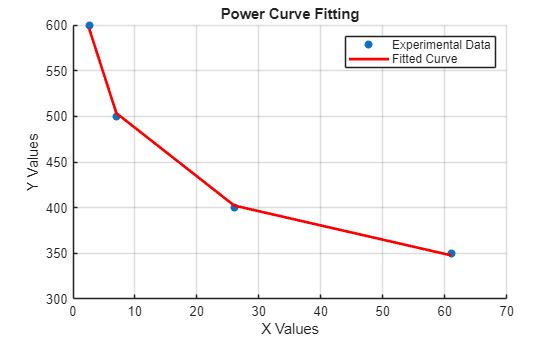

Goodness of Fit (R^2) = 0.9990



% Fitted values
y_fitted = a * x.^b;

% Plot
figure
scatter(x, y)
hold on
plot(x, y_fitted)
grid on

xlabel('X Values')
ylabel('Y Values')
title('Power Curve Fitting')
legend('Experimental Data', 'Fitted Curve')